# Laboratorio - Analisis y simulacion de robot industrial

## **Sebastian Felipe Alfonso Roa**

## **Ángel Esteban Díaz Sarmiento**

## **Sergio Esteban Quintero Benavides**

## **Juan Felipe Romero Sanabria** 

## Parte 1: Robot y Ruta

### 4. Localización de ruta 

A partir de las rutas sugeridas se seleccionó la ruta rectangular con esquinas curvas, de acuerdo al gráfico de la siguiente figura se crea la trayectoria a trozos en un plano XY que posteriormente será rotado y transladado al espacio de trabajo del robot.

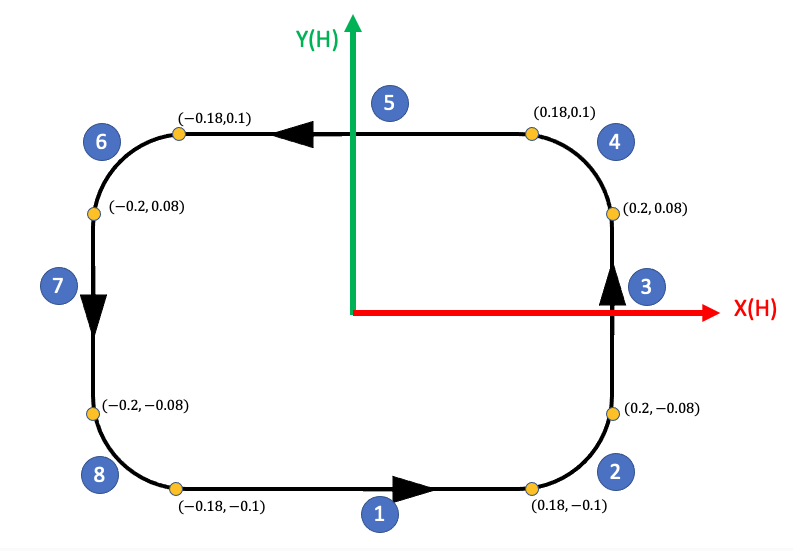

clc;clear;close all

Como se ve en la figura anterior, las coordenadas de la trayectoria son función del alcance horizontal del robot. Para el robot que se analizará en el presente trabajo el alcance horizontal (H) es igual a 700mm. Para poder escalar la trayectoria basta con multiplicar los parámetros de la misma por el alcance H como se muestra a continuación.

H=700;
a = 0.18*H; %distancia en x
b = 0.1*H;  %distancia en y
c = 0.08*H; %centro en y de los semicirculos
r = 0.02*H; %radio 

La trayectoria fue generada por segmentos de curvas y rectas concatenados entre sí comenzando en la coordenada (-0.18,-0.1) en sentido horario como se muestra a continuación.

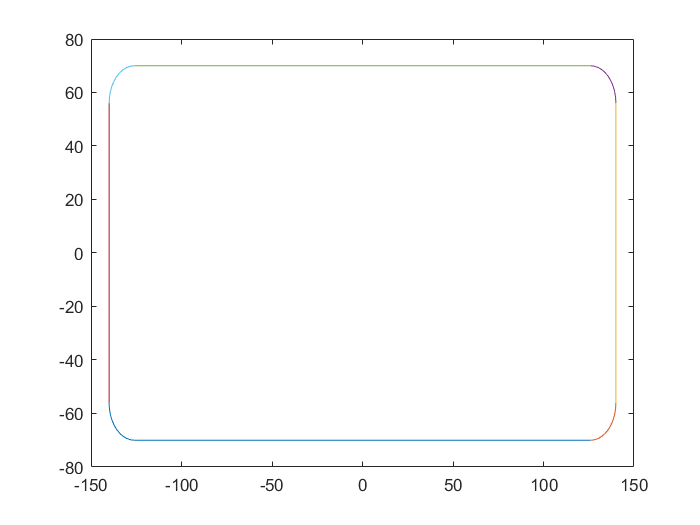

%%Ruta 1
x = -a:0.01:a;
len = size(x);
y = -b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = R1;

figure()
plot(x,y);
hold on

%%Ruta 2
t = 3*pi/2:pi/20:2*pi;
x = r*cos(t)+a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 3
y = -c:0.01:c;
len = size(y);
x = (a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 4
t = 0:pi/20:pi/2;
x = r*cos(t)+a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 5
x = a:-0.01:-a;
len = size(x);
y = b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 6
t = pi/2:pi/20:pi;
x = r*cos(t)-a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 7
y = c:-0.01:-c;
len = size(y);
x = -(a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 8
t = pi:pi/20:3*pi/2;
x = r*cos(t)-a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];

traye = [traye,R1];
plot(x,y);
hold off

La trayectoria elegida debe realizarse en el plano asignado para este ejercicio. En este caso particular, el plano debe ser perpendicular al vector [-1,0,1]. Para rotar la trayectoria se crea una matriz de rotación la cual permita obtener la orientación deseada.

%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];

Finalmente se dejan enunciados los parámetros de desplazamiento de la trayectoria para posteriormente poder ubicarla en el espacio diestro del robot como se solicitó.

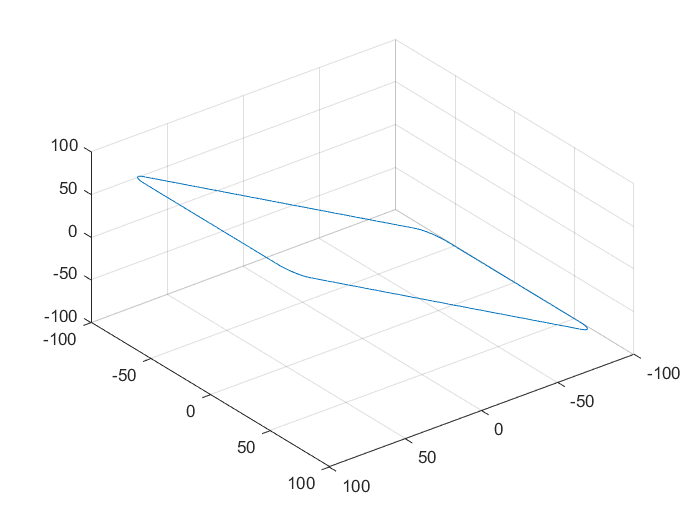

% Desplazamiento
x = 0;
y = 0;
z = 0;

%% Rotacion y dezplazamiento de la trayectoria

len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = x + traye(1,:);
traye(2,:) = y + traye(2,:);
traye(3,:) = z + traye(3,:);

figure
plot3(traye(1,:),traye(2,:),traye(3,:))
grid on
view([142 47])

### 5. Características y modelo del robot

#### 1. Imagen del robot. https://www.robots.com/robots/fanuc-lr-mate-200ib

http://geek.nmt.edu/~bruder/final_project_files/Fanuc%20LR%20Mate_200ib_200ib_3l.pdf

			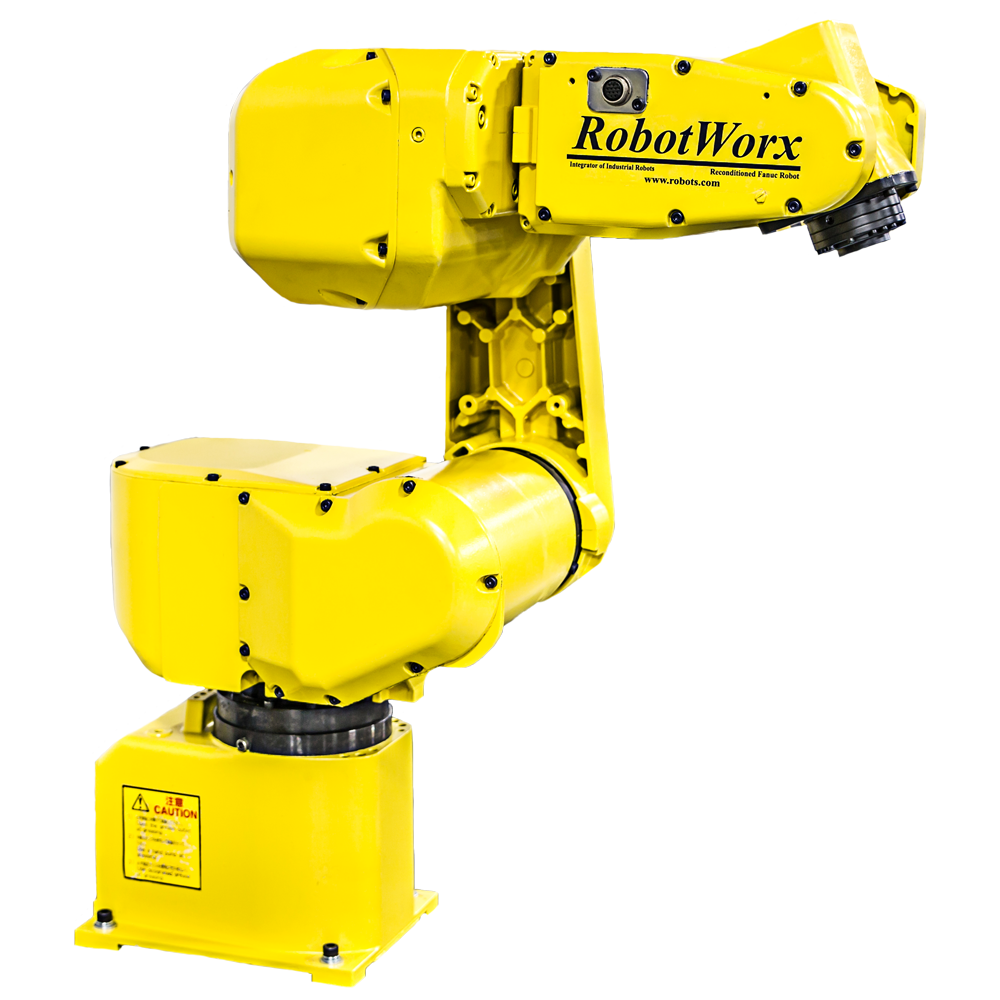		

#### 2. Capacidad de carga 

5 kg.

#### 3. Alcance vertical y horizontal. 

H-Reach: 700 mm

V-Reach-Max: 550 mm		

#### 4. Repetibilidad. 

± 0.04mm

#### 5. Gráfica(s) de espacio alcanzable.

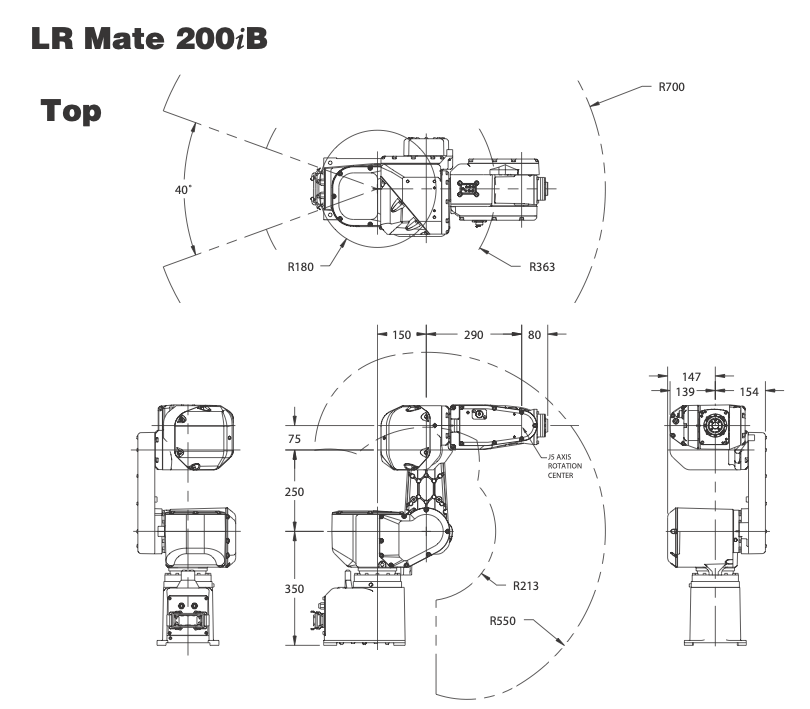

#### 6. Tabla de parámetros DH.

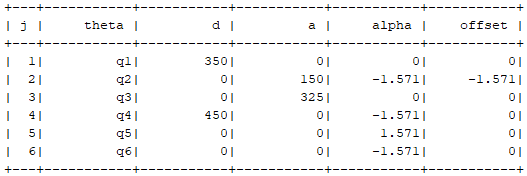

#### 7. ¿Qué software utiliza el fabricante para diseño de celdas o programación? 

FANUC ROBOGUIDE SIMULATION SOFTWARE

## Parte II: Modelos

### 6. Iniciando

#### Haciendo uso de MATLAB® y los Toolbox construya un modelo del robot o utilice uno disponible en los Toolbox y que corresponda al robot asignado. 

#### 1. Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.

En la figura que se muestra a continuación se ubicaron los sistemas coordenados sobre las articulaciones del robot para establecer el modelo DH módificado del mismo utilizando los objetos Link y SerialLink del Toolbox de Peter Corke.

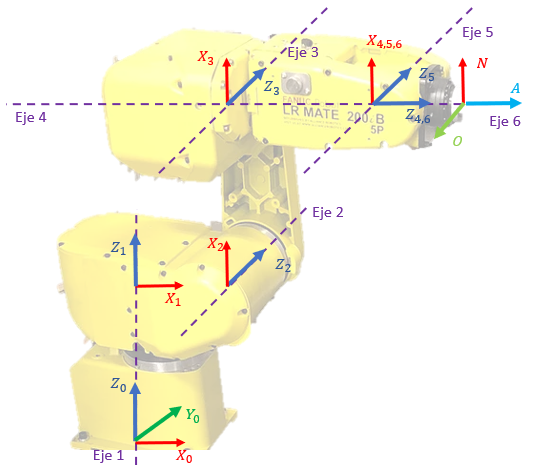

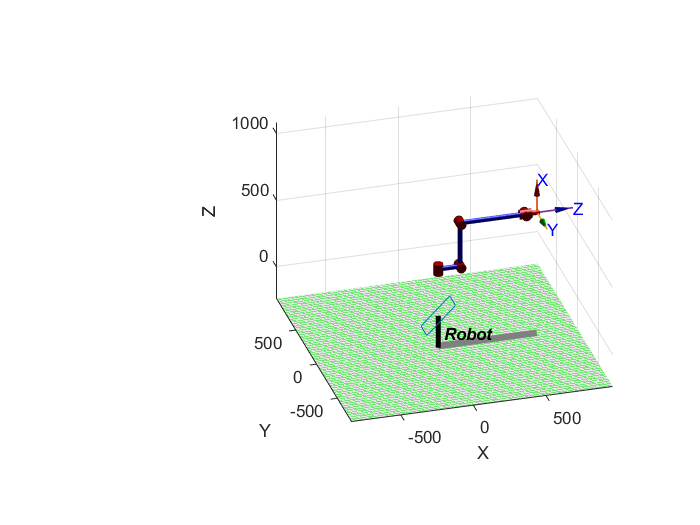

l0 = 350; l1 = 150; l2 = 250+75; l3 = 450;l4 = 80;
ws= [-70 80 -70 80 -20 90]*12;
plot_options = {'workspace',ws,'scale',0.5,'view',[-100 30], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha',     0,'a',   0, 'd',  l0,'offset',    0, 'qlim',        [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha', -pi/2,'a',  l1, 'd',   0,'offset',-pi/2, 'qlim',       [-7*pi/36 5*pi/6],   'modified');
L(3) = Link('revolute'  ,'alpha',     0,'a',  l2, 'd',   0,'offset',    0, 'qlim',   [-241*pi/180 5*pi/12],   'modified');
L(4) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',  l3,'offset',    0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',   0,'offset',    0, 'qlim',        [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',   0,'offset',    0, 'qlim',            [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);
Robot.tool = [1,0,0,0;
              0,1,0,0;
              0,0,1,l4;
              0,0,0,1];
Robot.teach()
view([-16 28])

MTH01 = L(1).A(0);
MTH12 = L(2).A(0);
MTH23 = L(3).A(0);
MTH34 = L(4).A(0);
MTH45 = L(5).A(0);
MTH56 = L(6).A(0);
MTH6T = Robot.tool;

#### 2. Considerando el robot asignado, construya el modelo del robot utilizando RST.

Posteriormente, utilizando el Robotics Systems Toolbox se crean los eslabones del robot con sus respectivas articulaciones para posteriormente ensamblarlos entre sí en un árbol de cuerpos rigidos como se ilustra a continuación.

robotRST = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = 0;
tform1 = trvec2tform([0 0 l0]);
setFixedTransform(jnt1,tform1);
body1.Joint = jnt1;

addBody(robotRST,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = 0;
tform2 = trvec2tform([l1 0 0])*eul2tform([0 -pi/2 -pi/2]);
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;

addBody(robotRST,body2,'body1')

body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0;
tform3 = trvec2tform([l2 0 0]);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;

addBody(robotRST,body3,'body2')

body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0;
tform4 = trvec2tform([0 l3 0])*eul2tform([0 0 -pi/2]);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;

addBody(robotRST,body4,'body3')

body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0;
tform5 = eul2tform([0 0 pi/2]);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;

addBody(robotRST,body5,'body4')

body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0;
tform6 = eul2tform([0 0 -pi/2]);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;

addBody(robotRST,body6,'body5')

bodyEndEffector = rigidBody('endeffector');
tformEfec = trvec2tform([0 0 l4]);
setFixedTransform(bodyEndEffector.Joint,tformEfec);
addBody(robotRST,bodyEndEffector,'body6');

figure()
show(robotRST)

ans =   Axes (Primary) with properties:

             XLim: [-1129 1129]
             YLim: [-1129 1129]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


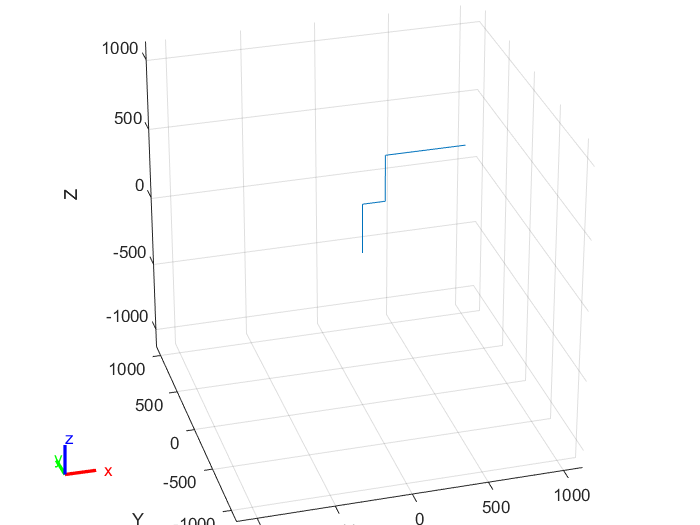

view([-16 28])
hold off

#### 3. Compare los dos métodos.

Comparando los resultados obtenidos con ambos Toolbox para hallar la posición del efector final respecto a la base en la configuración de home, se puede ver que los resultados son consistentes entre ambos métodos.

MTH0T = MTH01*MTH12*MTH23*MTH34*MTH45*MTH56*MTH6T

MTH0T =     0.0000    0.0000    1.0000  680.0000
   -0.0000   -1.0000    0.0000    0.0000
    1.0000   -0.0000   -0.0000  675.0000
         0         0         0    1.0000


config = homeConfiguration(robotRST);
tform = getTransform(robotRST,config,'endeffector','base')

tform =     0.0000    0.0000    1.0000  680.0000
         0   -1.0000    0.0000    0.0000
    1.0000   -0.0000   -0.0000  675.0000
         0         0         0    1.0000


#### 4. Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

Utilizando la hoja técnica del controlador R-J3iB se puede ver que se tiene la siguiente configuración para realizar las pruebas de calibración del robot utilizando cinemática directa.

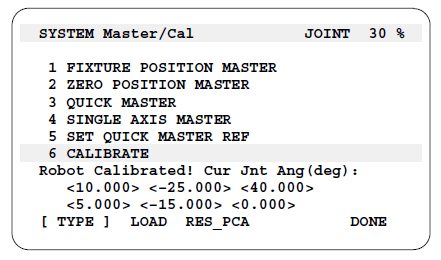

A continuación se procede a probar este punto de calibración utilizando los métodos de cinemática directa de cada uno de los Toolbox trabajdos.

q = deg2rad([10,-25,40,5,-15,0]);
Robot.fkine(q)

ans =     0.0137    0.1508    0.9885  519.5979
   -0.0831   -0.9850    0.1514   89.7867
    0.9964   -0.0842   -0.0010  528.0054
         0         0         0    1.0000


c1 = num2cell(q);
s = homeConfiguration(robotRST);
[s.JointPosition] = c1{:};
tform = getTransform(robotRST,s,'endeffector','base')

tform =     0.0137    0.1508    0.9885  519.5979
   -0.0831   -0.9850    0.1514   89.7867
    0.9964   -0.0842   -0.0010  528.0054
         0         0         0    1.0000


### 7. Modelo Geométrico Directo			

#### 1. Halle el modelo geométrico directo de su robot asignado usando MTH.

Hallando las MTH de cada eslabón de manera simbólica se procede a multiplicarlas entre sí para obtener la matriz MTH desde la base hasta el efector final en terminos de los valores articulares del robot.

threshold = 1e-8;
syms theta1 theta2 theta3 theta4 theta5 theta6
MTH_01 = mapSymType(L(1).A(theta1),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_12 = mapSymType(L(2).A(theta2),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_23 = mapSymType(L(3).A(theta3),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_34 = mapSymType(L(4).A(theta4),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_45 = mapSymType(L(5).A(theta5),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_56 = mapSymType(L(6).A(theta6),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_6T = Robot.tool;
MTH_0T = MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*MTH_6T;
MTH_0T = simplify(MTH_0T)

#### 2. Haciendo uso del modelo cinemático directo obtenga los valores de posición y de orientación en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares: 

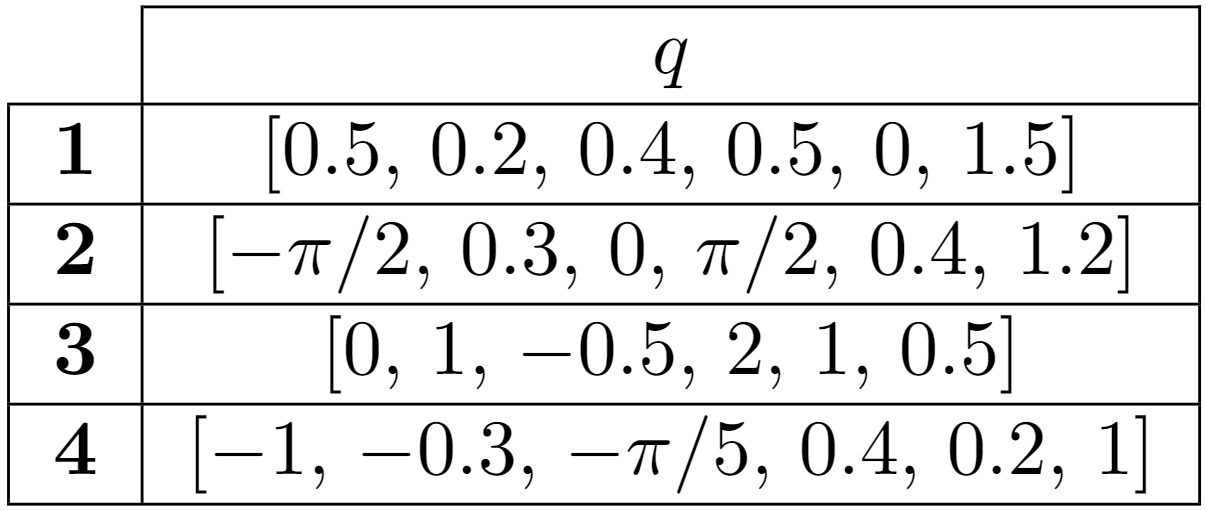

Teniendo en cuenta que se desea obtener la orientación del efector final en ángulos fijos $\left(\phi \left(\textrm{roll}\right),\theta \;\left(\textrm{pitch}\right),\psi \;\left(\textrm{yaw}\right)\right)$ se tiene que el modelo de la MTH del efector final respecto a la base es el siguiente:

syms phi theta psi x y z

MTH_Robot2 = transl(x,y,z)*trotz(psi)*troty(theta)*trotx(phi)

$$MTH\_Robot2 = \left(\begin{array}{cccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & x\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & y\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Con los elementos de la matriz anterior es posible despejar las variables de posición y orientación del efector final así:


$$x={{\textrm{MTH}}^{0T} }_{1,4}$$



$$y={{\textrm{MTH}}^{0T} }_{2,4}$$



$$z={{\textrm{MTH}}^{0T} }_{3,4}$$



$$\phi =\tan^{-1} \left(\frac{{{\textrm{MTH}}^{0T} }_{3,2} }{{{\textrm{MTH}}^{0T} }_{3,3} }\right)$$



$$\theta =\sin^{-1} \left({{-\textrm{MTH}}^{0T} }_{3,1} \right)$$



$$\psi =\tan^{-1} \left(\frac{{{\textrm{MTH}}^{0T} }_{2,1} }{{{\textrm{MTH}}^{0T} }_{1,1} }\right)$$


x = simplify(MTH_0T(1,4))

$$x = 150\,\cos\left(\theta_{1}\right)+325\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-450\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-80\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)+450\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)+80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{5}\right)-80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{5}\right)-80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{5}\right)$$

y = simplify(MTH_0T(2,4))

$$y = 150\,\sin\left(\theta_{1}\right)+325\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+80\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)-450\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+450\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)-80\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{5}\right)-80\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{5}\right)$$

z = simplify(MTH_0T(3,4))

$$z = 325\,\cos\left(\theta_{2}\right)-450\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-450\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{3}\right)-80\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{2}\right)-80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)+80\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{5}\right)+350$$

theta = simplify(asin(-MTH_0T(3,1)))

$$theta = \mathrm{asin}\left(\cos\left(\theta_{6}\right)\,\left(\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{5}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\right)+\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)\right)$$

phi = simplify(atan2(MTH_0T(3,2),MTH_0T(3,3)))

$$phi = \text{atan2}\left(\sin\left(\theta_{6}\right)\,\left(\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{5}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right),-\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{5}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\right)$$

psi = atan2(MTH_0T(2,1),MTH_0T(1,1))

$$psi = \text{atan2}\left(\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{5}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)\right),\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{5}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)\right)\right)$$

De esta manera, basta con hallar el valor númerico de la matriz MTH del efector final a la base con los valores articulares dados y hallar los valores de posición y orientación en cada configuración.

q1 = [0.5,0.2,0.4,0.5,0,1.5];
q2 = [-pi/2,0.3,0,pi/2,0.4,1.2];
q3 = [0,1,-0.5,2,1,0.5];
q4 = [-1,-0.3,-pi/5,0.4,0.2,1];

MTH_Robot1 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q1))

MTH_Robot1 =     0.2297   -0.6501    0.7243  572.1798
   -0.9106    0.1191    0.3957  312.5832
   -0.3435   -0.7505   -0.5646  369.2611
         0         0         0    1.0000


x = MTH_Robot1(1,4);
y = MTH_Robot1(2,4);
z = MTH_Robot1(3,4);
theta = asin(-MTH_Robot1(3,1));
phi = atan2(MTH_Robot1(3,2),MTH_Robot1(3,3));
psi = atan2(MTH_Robot1(2,1),MTH_Robot1(1,1));
X1= [x;y;z;phi;theta;psi]'

X1 =   572.1798  312.5832  369.2611   -2.2158    0.3506   -1.3237


MTH_Robot2 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q2));
x = MTH_Robot2(1,4);
y = MTH_Robot2(2,4);
z = MTH_Robot2(3,4);
theta = asin(-MTH_Robot2(3,1));
phi = atan2(MTH_Robot2(3,2),MTH_Robot2(3,3));
psi = atan2(MTH_Robot2(2,1),MTH_Robot2(1,1));
X2= [x;y;z;phi;theta;psi]'

X2 =    31.1535 -746.3393  505.7249   -2.4212    1.2002    2.7428


MTH_Robot3 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q3));
x = MTH_Robot3(1,4);
y = MTH_Robot3(2,4);
z = MTH_Robot3(3,4);
theta = asin(-MTH_Robot3(3,1));
phi = atan2(MTH_Robot3(3,2),MTH_Robot3(3,3));
psi = atan2(MTH_Robot3(2,1),MTH_Robot3(1,1));
X3= [x;y;z;phi;theta;psi]'

X3 =   869.7537   61.2118  313.7186   -1.4542    1.1427   -0.5920


MTH_Robot4 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q4));	
x = MTH_Robot4(1,4);
y = MTH_Robot4(2,4);
z = MTH_Robot4(3,4);
theta = asin(-MTH_Robot4(3,1));
phi = atan2(MTH_Robot4(3,2),MTH_Robot4(3,3));
psi = atan2(MTH_Robot4(2,1),MTH_Robot4(1,1));
X4= [x;y;z;phi;theta;psi]'

X4 = 	1.0e+03 *

    0.2118   -0.3183    1.0748   -0.0008   -0.0002   -0.0026


Los resultados obtenidos se reunen en la siguiente tabla:

#### 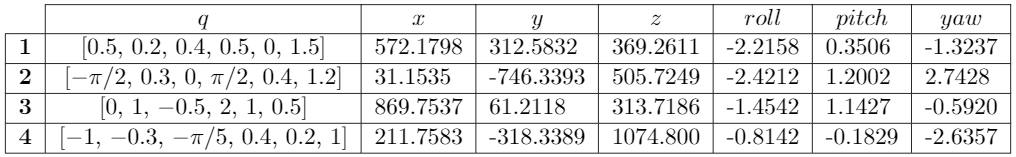

#### 3. Haga uso de las funciones de cinemática directa de ambos Toolbox y compruebe los resultados anteriores. 

**Peter corke**

PMTH=Robot.fkine(q1);
X1=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X1 =   572.1798  312.5832  369.2611   -2.2158    0.3506   -1.3237


PMTH=Robot.fkine(q2);
X2=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X2 =    31.1535 -746.3393  505.7249   -2.4212    1.2002    2.7428


PMTH=Robot.fkine(q3);
X3=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X3 =   869.7537   61.2118  313.7186   -1.4542    1.1427   -0.5920


PMTH=Robot.fkine(q4);
X4=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X4 = 	1.0e+03 *

    0.2118   -0.3183    1.0748   -0.0008   -0.0002   -0.0026


**RST**

c1 = num2cell(q1);
c2 = num2cell(q2);
c3 = num2cell(q3);
c4 = num2cell(q4);
s = homeConfiguration(robotRST);
[s.JointPosition] = c1{:};
tform = getTransform(robotRST,s,'endeffector','base');
X1=[tform2trvec(tform)';flip(tform2eul(tform)')]'

X1 =   572.1798  312.5832  369.2611   -2.2158    0.3506   -1.3237


[s.JointPosition] = c2{:};
tform = getTransform(robotRST,s,'endeffector','base');
X2=[tform2trvec(tform)';flip(tform2eul(tform)')]'

X2 =    31.1535 -746.3393  505.7249   -2.4212    1.2002    2.7428


[s.JointPosition] = c3{:};
tform = getTransform(robotRST,s,'endeffector','base');
X3=[tform2trvec(tform)';flip(tform2eul(tform)')]'

X3 =   869.7537   61.2118  313.7186   -1.4542    1.1427   -0.5920


[s.JointPosition] = c4{:};
tform = getTransform(robotRST,s,'endeffector','base');
X4=[tform2trvec(tform)';flip(tform2eul(tform)')]' 

X4 = 	1.0e+03 *

    0.2118   -0.3183    1.0748   -0.0008   -0.0002   -0.0026


#### 4. Compare los metodos. 

Como se mostró anteriormente se llega a los mismos resultados utilizando los tres métodos implementados de cinemática directa, es importante mencionar que para el caso del Toolbox de Peter Corke se debe configurar la convención de las rotaciones en ángulos fijos con el valor 'zyx'. Esta es la configuración por defecto en el Robotics Systems Toolbox, por lo que se omite este parámetro. En las funciones de ambos Toolbox se debe invertir el orden del vector para poder expresar la orientación primero respecto al eje "x", luego el eje "y" y finalmente el eje "z".					

#### 5. Elija uno de los metodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo Slider, visualizar el robot y la posición del efector final. 

#### 6. En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones. 

X1=

X2=

X3=

X4=

## 8. Modelo Geométrico Inverso 			

#### 1. Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. 

Utilizando la aproximación de desacople cinemático, se realizan los siguiente esquemas para determinar la cinemática inversa de la posición.

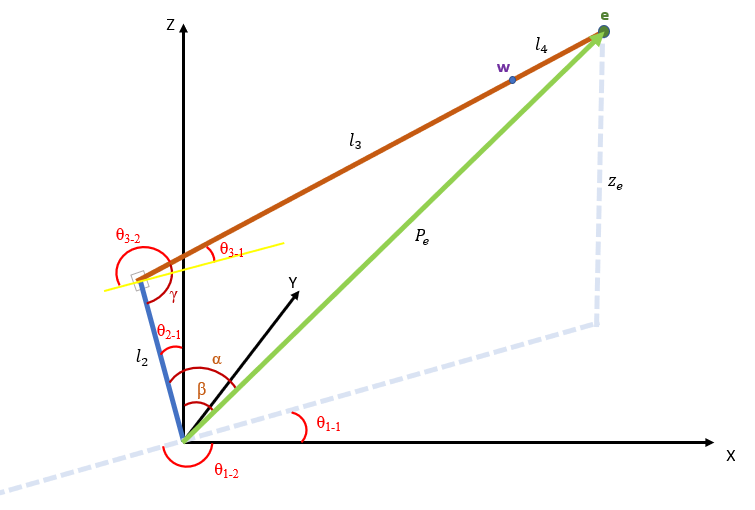

Se define el vector $e$ con las componentes correspondientes.


$$e=\left\lbrack \begin{array}{c}
x_e \\
y_e \\
z_e 
\end{array}\right\rbrack$$
 

A partir del plano X-Y se determinan las dos posibles soluciones para $\theta_1$.


$$$$\theta_{1-1} = atan2\left(\frac{y_e}{x_e}\right)$$

$$\theta_{1-2} = -\pi+atan2\left(\frac{y_e}{x_e}\right)$$$$


Con la magnitud del vector $e$ y el teroema del coseno se definen los ángulos $\alpha$ y $\beta \;$que determinanan las dos posibles solicuciones para $\theta_2$.


$$


$$P_e= \sqrt{x_e^2+y_e^2+z_e^2}$$$$



$$
(l_3+l_4)^2=L_2^2+P_e^2-2\cdot l_2\cdot P_e\cdot\cos(\alpha)\\

\cos(\alpha)=\frac{l_2^2+P_e^2-(l_3+l_4)^2}{2\cdot l_2\cdot P_e} \\

\alpha= \arccos\left(\frac{l_2^2+P_e^2-(l_3+l_4)^2}{2\cdot l_2\cdot P_e}\right)

$$



$$cos(\beta)=\frac{\sqrt{x_e^2+y_e^2}}{P_e}\\
\beta=arccos\left(\frac{\sqrt{x_e^2+y_e^2}}{P_e}\right)

$$



$$$$\theta_{2-1}= \alpha-\beta$$

$$\theta_{2-2}= \alpha+\beta$$$$
    

Nuevamente, a partir del vector $e$ y del teorema del coseno para el ángulo $\gamma$ se determinan las cuatro posibles soluciones para $\theta_3$.


$$P_e^2=l_2+(l_3+l_4)^2-2\cdot l_2\cdot (l_3+l_4) \cdot cos(\gamma)\\
cos(\gamma)=\frac{l_2+(l_3+l_4)^2-P_e^2}{2\cdot l_2\cdot (l_3+l_4)}\\
\gamma=arccos\left(\frac{l_2+(l_3+l_4)^2-P_e^2}{2\cdot l_2\cdot (l_3+l_4)}\right)$$



$$\theta_{3-1}=\pm \left(\gamma -\frac{\pi}2 \right)\\
\theta_{3-2}=\pm \left(\gamma -\frac{3\pi}2\right)$$


Conociendo que la orientación de la muñeca corresponde a la orientación de la base hasta el sistema coordenado 3 se puede expresar esta orientación de la siguiente forma:


$$O_w =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
1 & 0 & 0
\end{array}\right\rbrack \cdot \;\textrm{Rot}\left(x,\theta_1 \right)\cdot \;\textrm{Rot}\left(y,\theta_2 +\theta_3 \right)$$


Por la configuración del robot se puede ver que el efector final cambia su orientación gracias a los ejes 4, 5 y 6 que se encuentran intersectados en el punto $w$ lo cual se puede expresar en rotaciones de Euler ZYZ para de este modo hallar el valor de $\theta_4$, $\theta_5$ y $\theta_6$


$$$$O_e=O_w\cdot Rot(z,\theta_4) \cdot Rot(y,\theta_5)\cdot Rot(z,\theta_6)$$

$$R=O_w^{-1}\cdot O_e = Rot(z,\theta_4) \cdot Rot(y,\theta_5)\cdot Rot(z,\theta_6)$$$$


Es evidente que la forma de la matriz anterior es:

syms theta4 theta5 theta6
R = rotz(theta4)*roty(theta5)*rotz(theta6)

$$R = \left(\begin{array}{ccc} \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\\ \cos\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)+\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right)\,\cos\left(\theta_{6}\right)-\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & \sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\\ -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{5}\right) & \sin\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{5}\right) \end{array}\right)$$

Despejando se encuentra que:


$$\theta_4 =\tan^{-1} \left(\frac{R_{2,3} }{R_{1,3} }\right)$$



$$\theta_5 =\cos^{-1} \left(R_{3,3} \right)$$



$$\theta_6 =\tan^{-1} \left(\frac{R_{3,2} }{-R_{3,1} }\right)$$


#### 2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones. 

Considerando todas las posibles configuraciones que pueden resultar en la misma posición y orientación del efector final, se determinan 4 posibles soluciones.

#### 3. Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox, explique: 	

#### ¿Cuál es la diferencia entre estas funciones? 

- **ikine: **Cinemática inversa para robots de 6 o más grados de libertad con muñeca esférica. También puede ser usado para robots de 3 grados de libertad, pasando como parámetro una mascara con esta información. 

- **ikinei3: **Cinemática inversa para robots de 3 grados de libertad. Es la misma funcion **ikine6 **pero sin la muñeca.

- **ikine6s: **Cinemática inversa analítica para robots de 6 grados de libertad con muñeca esférica. Trata los siguientes casos específicos como el robot Kuka KR5 con muchas compensaciones (7 parámetros de longitud), Brazos Puma 560 con compensación de hombros y codos (4 parámetros de longitud) y Robot con un hombro desplazado y una tercera articulación prismática (como el brazo de Stanford). Además, los robots deben estar definidos usando DH estandar.

- **ikine_sym: **Devuelve la solucion simbólica en forma de cell array y muestras todas las posibles soluciones.

- **ikinem: **Inversa numérica por minimización que se encuentra en desarrollo. Devuleve la solución al llegar a un mínimo local.	

#### ¿Cuál debe usar para su robot y por qué? (Revise la documentacion del Toolbox)

LR Mate 200ib es un robot de 6 grados de libertad con muñeca esférica, pues 3 articulaciones intersectan sus ejes. Por lo tanto, se puede utilizar la función **ikine.**

**Cinemática inversa usando la funcion ikine del toolbox RVC:**

q1 = Robot.ikunc(MTH_Robot1,[0.1 0.1 0.1 0 0 1])

q1 =     0.5000    0.2000    0.4000    0.5115   -0.0000    1.4885


q2 = Robot.ikunc(MTH_Robot2)

q2 =    -1.5708    0.3000   -0.0000    1.5708    0.4000    1.2000


q3 = Robot.ikunc(MTH_Robot3)

q3 =    -0.0000    1.0000   -0.5000    2.0000    1.0000    0.5000


q4 = Robot.ikunc(MTH_Robot4)

q4 =    -1.0000   -0.3000   -0.6283    0.4000    0.2000    1.0000


#### 4. Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores. Compare los metodos. 			

ik = inverseKinematics('RigidBodyTree',robotRST);
weights = [0.25 0.25 0.25 1 1 1];
c1 = num2cell([0.1 0.1 0.1 0 0 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot1),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


c1 = num2cell([-1 0.1 0 1 0.1 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot2),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


c1 = num2cell([0.1 0.1 0.1 0.1 0 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot3),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


c1 = num2cell([0.1 0.1 0.1 0.1 0 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot4),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


#### 5. Compare los métodos.

En esta ocasión, la naturaleza del problema de resolver la cinemática inversa puede tener diferentes soluciones e incluso dependiendo del algoritmo puede no tener solución. Por ejemplo, el Toolbox P**erter Corke** no fue capaz de resolver la posición X2, mientras que el Toolbox **RST** en todos los casos fue capaz de encontrar una de las 4 posibles soluciones y en el caso donde la solución coincide con la configuración de articulaciones dadas inicialmente, la exactitud fue mayor a la dada por el Toolbox P**erter Corke.**				

#### 6. Calcule la configuración del robot para las siguientes posturas de la herramienta. Proponga 4 posturas (x,y,z,roll,pitch,yaw)′ que estén dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla. 

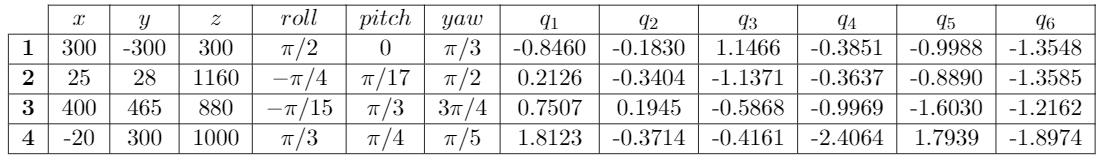

Primero se propone las siguientes posturas:

x1 = transl([300 -300 300])*rpy2tr(flip([pi/2 0 pi/3]),'zyx');
x2 = transl([25 28 1160])*rpy2tr(flip([-pi/4 pi/17 pi/2]),'zyx');
x3 = transl([400 465 880])*rpy2tr(flip([-pi/15 pi/3 3*pi/4]),'zyx');
x4 = transl([-20 300 1000])*rpy2tr(flip([pi/3 pi/4 pi/5]),'zyx');

Ahora usando el toolbox **RVC** se calcula la cinemática inversa:

s1 = Robot.ikunc(x1)

s1 =    -0.8450   -0.1830    1.1466   -0.3851   -0.9988   -1.3548


s2 = Robot.ikunc(x2)

s2 =     0.2126   -0.3404   -1.1371   -0.3637   -0.8890   -1.3585


s3 = Robot.ikunc(x3)

s3 =     0.7507    0.1945   -0.5868   -0.9969   -1.6030   -1.2162


s4 = Robot.ikunc(x4)

s4 =     1.8123   -0.3714   -0.4161   -2.4064    1.7939   -1.8974


#### 7. Haciendo uso de la GUI verifique que con la configuración calculada se obtiene la postura indicada de la herramienta.

X1=

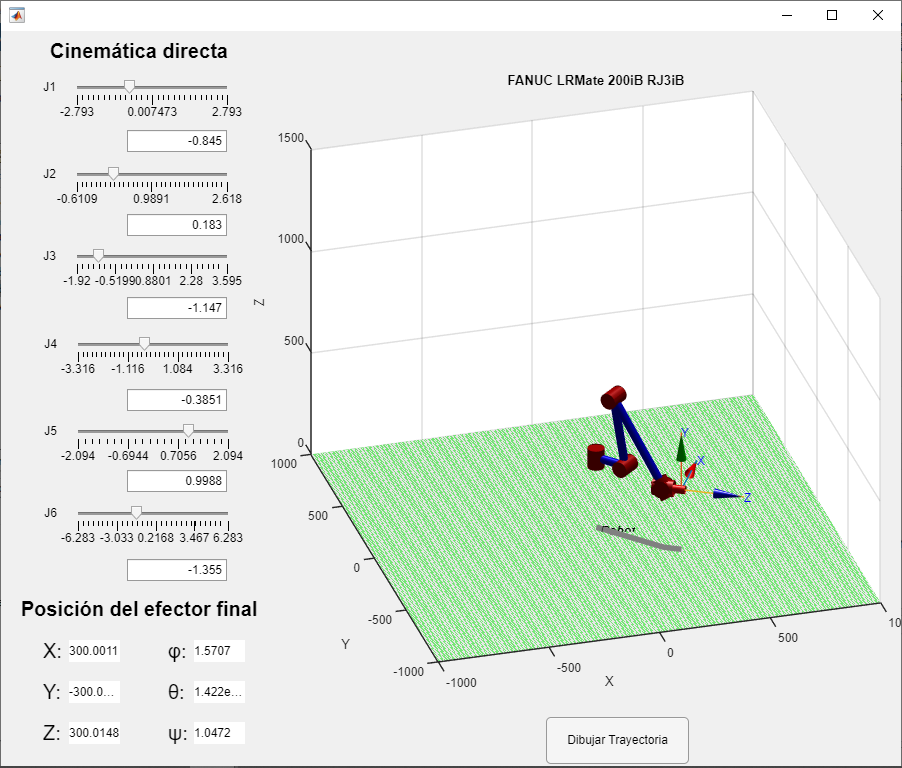

X2=

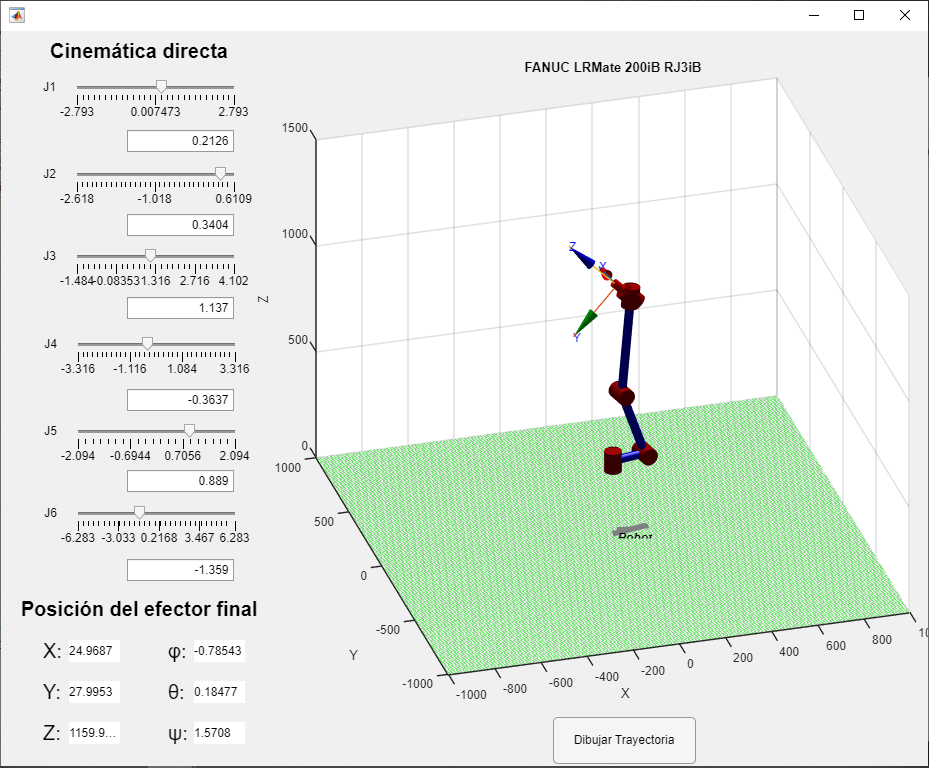

X3=

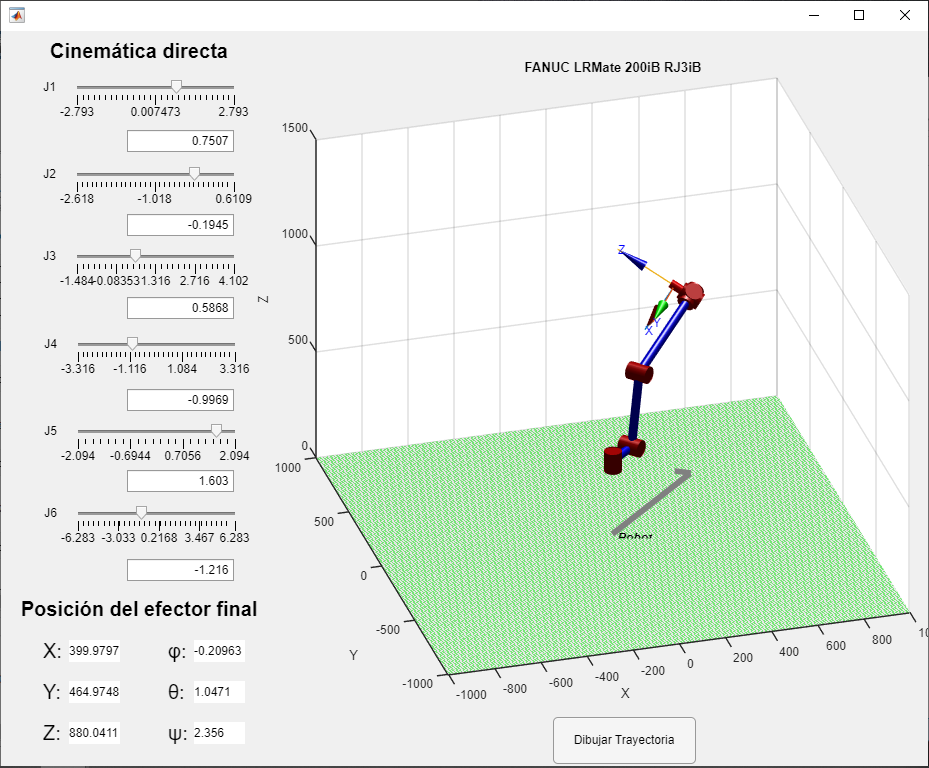

X4=

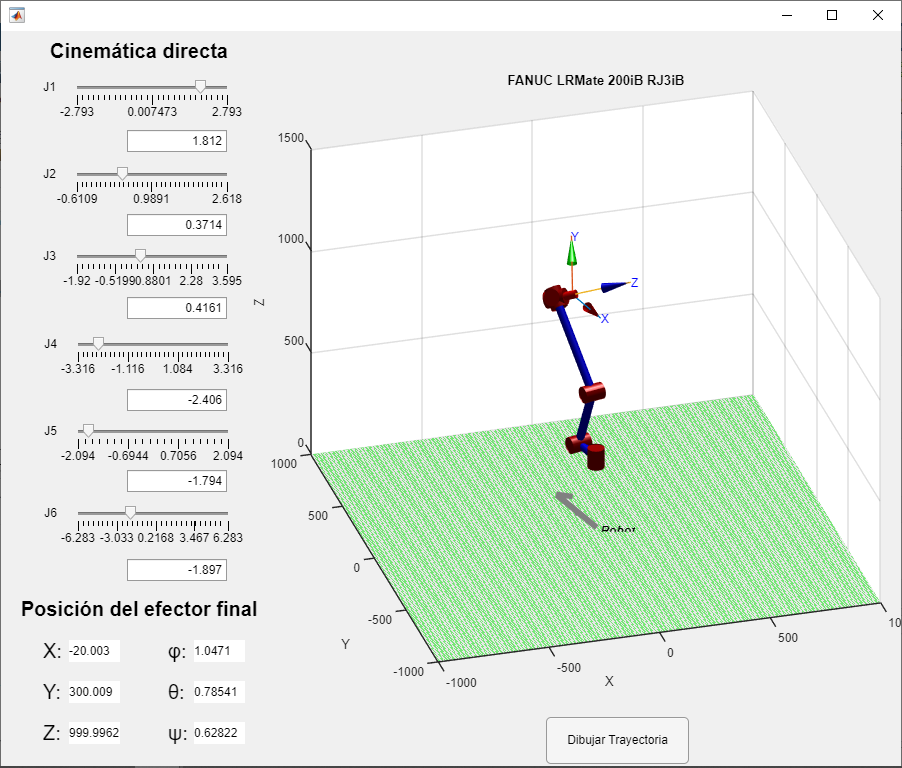

#### 8. Para uno de los cuatro casos haga capturas de pantalla resaltando con cotas los valores x y z, e incluya en el informe los resultados.

Para el primer caso:

X1=

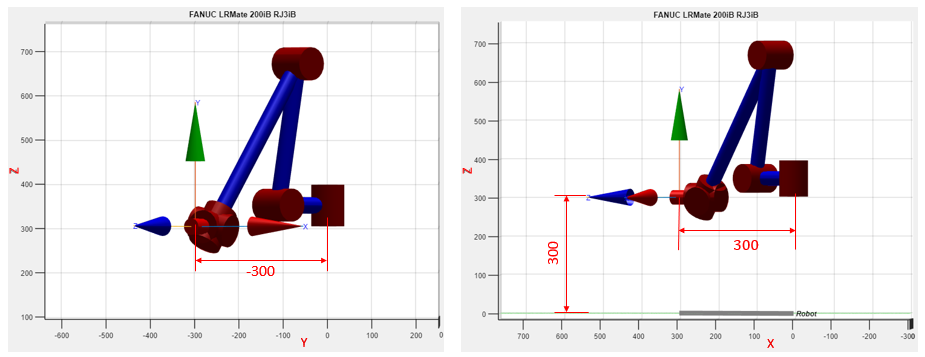

## Parte III: Modelo diferencial de primer Orden

#### Considerando que para que el robot ejecute los movimientos, se desea establecer una relaci´on entre las velocidades del efector final y las articulaciones

####     1. Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado, obtenga el Jacobiano (como una matriz de valores númericos, NO simbólico) en función de los ángulos de articulación.

Para obtener la matriz jacobiana de forma numérica se utilizaron las MTH que representan al robot en la posición de home, donde todas las articulaciones tienen el valor de 0.

MTH01 = L(1).A(0);
MTH12 = L(2).A(0);
MTH23 = L(3).A(0);
MTH34 = L(4).A(0);
MTH45 = L(5).A(0);
MTH56 = L(6).A(0);
MTH6T = Robot.tool;
MTH02 = MTH01*MTH12;
MTH03 = MTH02*MTH23;
MTH04 = MTH03*MTH34;
MTH05 = MTH04*MTH45;
MTH06 = MTH05*MTH56;
MTH0T = MTH06*MTH6T;
J1 = [cross(MTH01(1:3,3),(MTH0T(1:3,4)-MTH01(1:3,4)));MTH01(1:3,3)];
J2 = [cross(MTH02(1:3,3),(MTH0T(1:3,4)-MTH02(1:3,4)));MTH02(1:3,3)];
J3 = [cross(MTH03(1:3,3),(MTH0T(1:3,4)-MTH03(1:3,4)));MTH03(1:3,3)];
J4 = [cross(MTH04(1:3,3),(MTH0T(1:3,4)-MTH04(1:3,4)));MTH04(1:3,3)];
J5 = [cross(MTH05(1:3,3),(MTH0T(1:3,4)-MTH05(1:3,4)));MTH05(1:3,3)];
J6 = [cross(MTH06(1:3,3),(MTH0T(1:3,4)-MTH06(1:3,4)));MTH06(1:3,3)];
J = [J1,J2,J3,J4,J5,J6]

J =    -0.0000  325.0000   -0.0000    0.0000   -0.0000    0.0000
  680.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
         0 -530.0000 -530.0000   -0.0000  -80.0000   -0.0000
         0         0         0    1.0000         0    1.0000
         0    1.0000    1.0000    0.0000    1.0000    0.0000
    1.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000


Utilizando la primera postura propuesta en la sección de cinemática inversa se procede a calcular el Jacobiano con los valores articulares encontrados. Posteriormente, se hallan las velocidades articulares a partir de las velocidades lineales y angulares propuestas así:


$$\dot{q} =J^{-1} V$$


MTH01 = L(1).A(s1(1));
MTH12 = L(2).A(s1(2));
MTH23 = L(3).A(s1(3));
MTH34 = L(4).A(s1(4));
MTH45 = L(5).A(s1(5));
MTH56 = L(6).A(s1(6));
MTH6T = Robot.tool;
MTH02 = MTH01*MTH12;
MTH03 = MTH02*MTH23;
MTH04 = MTH03*MTH34;
MTH05 = MTH04*MTH45;
MTH06 = MTH05*MTH56;
MTH0T = MTH06*MTH6T;
J1 = [cross(MTH01(1:3,3),(MTH0T(1:3,4)-MTH01(1:3,4)));MTH01(1:3,3)];
J2 = [cross(MTH02(1:3,3),(MTH0T(1:3,4)-MTH02(1:3,4)));MTH02(1:3,3)];
J3 = [cross(MTH03(1:3,3),(MTH0T(1:3,4)-MTH03(1:3,4)));MTH03(1:3,3)];
J4 = [cross(MTH04(1:3,3),(MTH0T(1:3,4)-MTH04(1:3,4)));MTH04(1:3,3)];
J5 = [cross(MTH05(1:3,3),(MTH0T(1:3,4)-MTH05(1:3,4)));MTH05(1:3,3)];
J6 = [cross(MTH06(1:3,3),(MTH0T(1:3,4)-MTH06(1:3,4)));MTH06(1:3,3)];
J = [J1,J2,J3,J4,J5,J6]

J =   300.0001  -33.1866 -245.2993  -32.8512   -8.5738    0.0000
  300.0001   37.3986  276.4319  -56.8999  -14.8503    0.0000
         0 -273.5109 -332.6400   14.4181  -78.1406         0
         0    0.7480    0.7480    0.3787    0.4884    0.8660
         0    0.6637    0.6637   -0.4267    0.8459   -0.5000
    1.0000    0.0000    0.0000   -0.8213   -0.2143    0.0000


#### 2. Para la postura 1 de la tabla anterior obtenga las velocidades de articulación para: 


$$V_H =\left\lbrack \begin{array}{c}
100\\
200\\
50
\end{array}\right\rbrack \frac{m}{s}\;\;\;,\;\;\;\;\;\;\;\;\;\;\omega_H =\left\lbrack \begin{array}{c}
5\\
10\\
-5
\end{array}\right\rbrack \frac{\textrm{rad}}{s}$$


V = [100;200;50;5;10;-5];
q_dot = J^-1*V	

q_dot =     1.6889
   -6.6826
    1.4712
    3.6648
   17.1642
   -1.0074


## Parte IV: Integración 

#### Ahora con la ayuda de los algoritmos desarrollados y de la GUI construida. 

#### 1. Ubique la ruta seleccionada con la orientación indicada dentro del espacio diestro del robot. 

Con la matriz de rotación se ubica la trayectoria normal al vector deseado y las coordenadas dx, dy y dz representan la ubicación del centro de la trayectoria para que quede ubicada dentro del espacio diestro del robot.

clear; clc; close all;
%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];
% Desplazamiento
dx = 500;
dy = 0;
dz = 400;

#### 2. Defina un conjunto de puntos equidistantes que pertenezcan a la ruta (viapoints). Mínimo 60 puntos. El eje z de la herramienta debe mantenerse perpendicular al plano que contiene la ruta. 

Estimando el perímetro de la ruta se establece la distancia máxima entre los viapoints para generar mínimo 60 puntos en toda la trayectoria.

H=700;
a = 0.18*H; %distancia en x
b = 0.1*H;  %distancia en y
c = 0.08*H; %centro en y de los semicirculos
r = 0.02*H; %radio
dis_max = (a*4+c*4+2*pi*r)/60

dis_max = 13.5994

De esta manera se elige un delta de distancia menor al límite, asegurando así la cantidad de puntos propuesto para toda la trayectoria.

delta = 10;
%%Ruta 1
x = -a:delta:a;
len = size(x);
y = -b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = R1;

%%Ruta 2
t = 3*pi/2:delta/r:2*pi;
x = r*cos(t)+a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 3
y = -c:delta:c;
len = size(y);
x = (a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 4
t = 0:delta/r:pi/2;
x = r*cos(t)+a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 5
x = a:-delta:-a;
len = size(x);
y = b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 6
t = pi/2:delta/r:pi;
x = r*cos(t)-a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 7
y = c:-delta:-c;
len = size(y);
x = -(a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 8
t = pi:delta/r:3*pi/2;
x = r*cos(t)-a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];

traye = [traye,R1];

Finalmente, se aplican los parámetros de rotación y desplazamiento mencionados anteriormente.

% Rotacion y dezplazamiento de la trayectoria
len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = dx + traye(1,:);
traye(2,:) = dy + traye(2,:);
traye(3,:) = dz + traye(3,:);

plot3(traye(1,:),traye(2,:),traye(3,:))
xlim([-100 700])
ylim([-200 200])
zlim([0 900])
hold on

#### 3. Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articuación al recorrer la ruta. 

Primero se crea el robot con el Toolbox de **Peter Corke**.

l0 = 350; l1 = 150; l2 = 250+75; l3 = 450;l4 = 80;
ws= [-100 700 -200 200 0 900];
plot_options = {'workspace',ws,'scale',1,'view',[-16 28], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha',     0,'a',   0, 'd',  l0,'offset',    0, 'qlim',        [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha', -pi/2,'a',  l1, 'd',   0,'offset',-pi/2, 'qlim',       [-7*pi/36 5*pi/6],   'modified');
L(3) = Link('revolute'  ,'alpha',     0,'a',  l2, 'd',   0,'offset',    0, 'qlim',   [-241*pi/180 5*pi/12],   'modified');
L(4) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',  l3,'offset',    0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',   0,'offset',    0, 'qlim',        [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',   0,'offset',    0, 'qlim',            [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);
Robot.tool = [1,0,0,0;
              0,1,0,0;
              0,0,1,l4;
              0,0,0,1];
syms theta1 theta2 theta3 theta4 theta5 theta6
MTH01 = L(1).A(theta1);
MTH12 = L(2).A(theta2);
MTH23 = L(3).A(theta3);
MTH34 = L(4).A(theta4);
MTH45 = L(5).A(theta5);
MTH56 = L(6).A(theta6);
MTH6T = Robot.tool;
MTH02 = MTH01*MTH12;
MTH03 = MTH02*MTH23;
MTH04 = MTH03*MTH34;
MTH05 = MTH04*MTH45;
MTH06 = MTH05*MTH56;
MTH0T = MTH06*MTH6T;

Posteriormente, se evalua en la posición de "home" la matriz de transformación homogenea de la base a la herramienta del robot para así determinar la matriz de rotación base. Además, se aplica una rotación adicional alrededor del eje "y" para así asegurar la orientación solicitada del eje z de la herramienta. Finalmente, se procede a calcular la cinemática inversa con cada punto de la trayectoria creada, manteniendo la orientación del TCP constante en todo el recorrido.

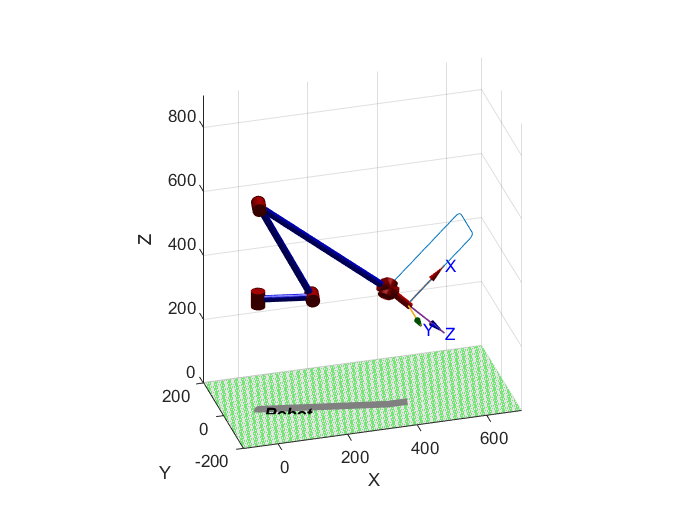

MTH0T = double(subs(MTH0T,[theta1,theta2,theta3,theta4,theta5,theta6],[0,0,0,0,0,0]));
R = tr2rt(MTH0T)*roty(-pi/4);
R = r2t(R);
for i=1:size(traye,2)
    t_act=traye(:,i);
    T = transl(t_act)*R;    
    q_act = Robot.ikunc(T);    
    if i==1
        q = q_act;
    else               
        q = [q;q_act];
    end   
    t_pas = t_act;
    q_pas = q_act;
end
Robot.plot(q)
view([-16 28])

Al terminar de realizar la trayectoria se obtienen los siguientes perfiles de posición ángular de cada articulación.

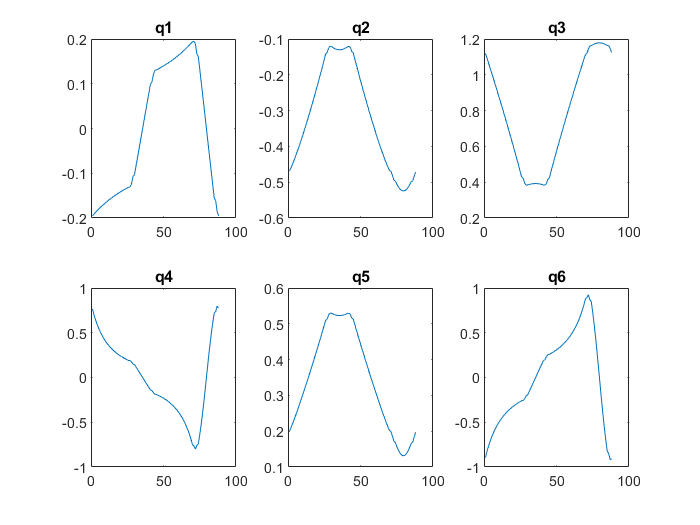

figure()
for i=1:6
    subplot(2,3,i)
    plot(q(:,i))
    title((sprintf('q%d', i)))
end

#### 4. Calcule las velocidades en cada viapoint de manera que la herramienta recorra la ruta a una velocidad de 500 mm/s. Presente gráficas de velocidad de cada articulación.

Con las MTH de cada articulación respecto a la base, se genera el Jacobiano geométrico que se utilizará para mantener la velocidad del TCP en el valor deseado.

J1 = [cross(MTH01(1:3,3),(MTH0T(1:3,4)-MTH01(1:3,4)));MTH01(1:3,3)];
J2 = [cross(MTH02(1:3,3),(MTH0T(1:3,4)-MTH02(1:3,4)));MTH02(1:3,3)];
J3 = [cross(MTH03(1:3,3),(MTH0T(1:3,4)-MTH03(1:3,4)));MTH03(1:3,3)];
J4 = [cross(MTH04(1:3,3),(MTH0T(1:3,4)-MTH04(1:3,4)));MTH04(1:3,3)];
J5 = [cross(MTH05(1:3,3),(MTH0T(1:3,4)-MTH05(1:3,4)));MTH05(1:3,3)];
J6 = [cross(MTH06(1:3,3),(MTH0T(1:3,4)-MTH06(1:3,4)));MTH06(1:3,3)];
Jsim = [J1,J2,J3,J4,J5,J6];

Debido a que el Jacobiano depende de la posición actual del robot, se debe realizar el cálculo numérico del mismo cada vez que el robot actualiza su posición. De la misma forma, se deben calcular en cada punto de la trayectoria las velocidades articulares sabiendo que se desea una velocidad contante del TCP. Para asegurar esto, el vector de velocidad lineal objetivo se encuentra en la misma dirección y sentido del vector director que va del punto actual al punto siguiente de la trayectoria pero su norma es igual a la velocidad deseada. Las velocidades angulares de la herramienta se mantienen constantes en 0.

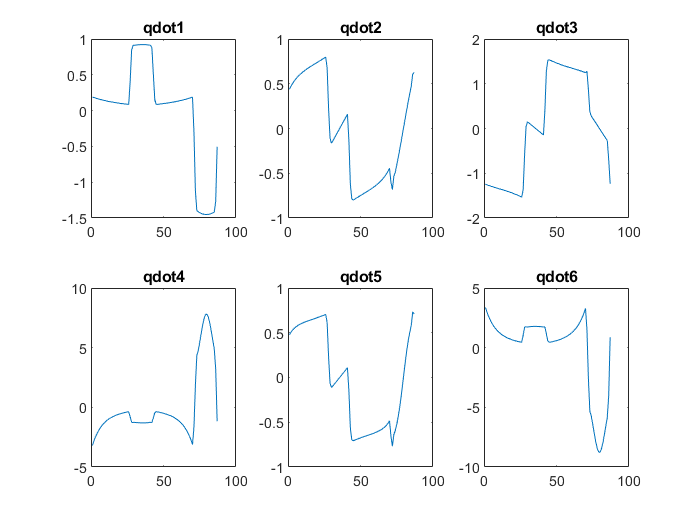

for i=1:size(traye,2)
    t_act=traye(:,i);
    T = transl(t_act)*R;    
    q_act = Robot.ikunc(T);    
    if i==1
        q = q_act;
    else
        J = double(subs(Jsim,[theta1,theta2,theta3,theta4,theta5,theta6],q_pas));
        vecT=(t_act-t_pas);
        vecT=vecT/norm(vecT)*500;
        q_dot_act = (J^-1*[vecT;0;0;0])';
        if i==2
            q_dot = q_dot_act;
        else
            q_dot = [q_dot;q_dot_act];
        end        
        q = [q;q_act];
    end   
    t_pas = t_act;
    q_pas = q_act;
end
figure()
for i=1:6
    subplot(2,3,i)
    plot(q_dot(:,i))
    title((sprintf('qdot%d', i)))
end